clear

MTOW = 32779 * 9.81;
WS = 3332;
srefref = MTOW/WS

srefref = 96.5072


AR = 8.5;
Sweep = 0;
Taper = 0.53;
c_bar = 3.48

c_bar = 3.4800


[T, a, P, rho] = atmosisa(25000*0.3048)

T = 238.6200

a = 309.6696

P = 3.7601e+04

rho = 0.5489

[T, a_sealevel, P, rho_sealevel] = atmosisa(0)

T = 288.1500

a_sealevel = 340.2941

P = 101325

rho_sealevel = 1.2250


V_stall_sealevel = sqrt(WS*2/(rho_sealevel*2.7))

V_stall_sealevel = 44.8867


fuselage_rad = 1.25;
twist = -3*pi/180;
panelnum = 100;
Cruise_Mach = 0.45

Cruise_Mach = 0.4500

Uinf = Cruise_Mach*a;
incidence = 4.6*pi/180;


airfoil(1).Field = 'root';
airfoil(1).alpha0 = -0.07;
airfoil(1).a = 6.68;
airfoil(2).Field = 'tip';
airfoil(2).alpha0 = -0.07;
airfoil(2).a = 6.68;


%% discritize planform to plot
[Sref, c_y, span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)

Sref = 96.7903

c_y =     4.4111    4.4096    4.4082    4.4067    4.4053    4.4039    4.4024    4.4010    4.3995    4.3981    4.3966    4.3952    4.3937    4.3923    4.3908    4.3894    4.3880    4.3865    4.3851    4.3836    4.3822    4.3807    4.3793    4.3778    4.3764    4.3749    4.3735    4.3720    4.3706    4.3692    4.3677    4.3663    4.3648    4.3634    4.3619    4.3605    4.3590    4.3576    4.3561    4.3547    4.3533    4.3518    4.3504    4.3489    4.3475    4.3460    4.3446    4.3431    4.3417    4.3402


span_disc =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


quarterchord =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0


MACpos = 645


semispan = length(span_disc)*0.01

semispan = 14.3500


thetadist = acos(span_disc/span_disc(end))

thetadist =     1.5708    1.5701    1.5694    1.5687    1.5680    1.5673    1.5666    1.5659    1.5652    1.5645    1.5638    1.5631    1.5624    1.5617    1.5610    1.5603    1.5596    1.5589    1.5582    1.5575    1.5568    1.5562    1.5555    1.5548    1.5541    1.5534    1.5527    1.5520    1.5513    1.5506    1.5499    1.5492    1.5485    1.5478    1.5471    1.5464    1.5457    1.5450    1.5443    1.5436    1.5429    1.5422    1.5415    1.5408    1.5401    1.5394    1.5387    1.5380    1.5373    1.5366



twist_dis = linspace(0,twist,length(span_disc))

twist_dis =          0   -0.0000   -0.0001   -0.0001   -0.0001   -0.0002   -0.0002   -0.0003   -0.0003   -0.0003   -0.0004   -0.0004   -0.0004   -0.0005   -0.0005   -0.0005   -0.0006   -0.0006   -0.0007   -0.0007   -0.0007   -0.0008   -0.0008   -0.0008   -0.0009   -0.0009   -0.0009   -0.0010   -0.0010   -0.0011   -0.0011   -0.0011   -0.0012   -0.0012   -0.0012   -0.0013   -0.0013   -0.0014   -0.0014   -0.0014   -0.0015   -0.0015   -0.0015   -0.0016   -0.0016   -0.0016   -0.0017   -0.0017   -0.0018   -0.0018


alpha_0_dis = linspace(airfoil(1).alpha0,airfoil(2).alpha0,length(span_disc))

alpha_0_dis =    -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700   -0.0700


incidence_dis = incidence*ones(1,length(span_disc))

incidence_dis =     0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803    0.0803


alpha_dis = twist_dis - alpha_0_dis + incidence_dis

alpha_dis =     0.1503    0.1502    0.1502    0.1502    0.1501    0.1501    0.1501    0.1500    0.1500    0.1500    0.1499    0.1499    0.1498    0.1498    0.1498    0.1497    0.1497    0.1497    0.1496    0.1496    0.1496    0.1495    0.1495    0.1494    0.1494    0.1494    0.1493    0.1493    0.1493    0.1492    0.1492    0.1492    0.1491    0.1491    0.1490    0.1490    0.1490    0.1489    0.1489    0.1489    0.1488    0.1488    0.1488    0.1487    0.1487    0.1486    0.1486    0.1486    0.1485    0.1485



a_dis = linspace(airfoil(1).a,airfoil(2).a,length(span_disc))

a_dis =     6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800    6.6800



mu_dis = (a_dis.*c_y)/(4.*AR*c_bar)

mu_dis =     0.2490    0.2490    0.2489    0.2488    0.2487    0.2486    0.2485    0.2485    0.2484    0.2483    0.2482    0.2481    0.2481    0.2480    0.2479    0.2478    0.2477    0.2476    0.2476    0.2475    0.2474    0.2473    0.2472    0.2472    0.2471    0.2470    0.2469    0.2468    0.2468    0.2467    0.2466    0.2465    0.2464    0.2463    0.2463    0.2462    0.2461    0.2460    0.2459    0.2459    0.2458    0.2457    0.2456    0.2455    0.2454    0.2454    0.2453    0.2452    0.2451    0.2450



LHS = zeros(floor(panelnum/2),1);
RHS = zeros(floor(panelnum/2),floor(panelnum/2));

for i = 1:floor(panelnum/2)
    for j = 1 : floor(panelnum/2)
%         tempind = floor((i*length(span_disc)/panelnum - length(span_disc)/(2*panelnum)));
        [temp,tempind]= min(abs(thetadist-i*pi/panelnum));
        LHS(i,1) = mu_dis(tempind)*alpha_dis(tempind)*sin(thetadist(tempind));
        RHS(i,j) = sin((2*j-1)*thetadist(tempind))*((2*j-1)*mu_dis(tempind) + sin(thetadist(tempind)));
    end
end
Aseries = RHS\LHS;
gamma_span_coef = 4*semispan*Uinf;
gamma_sum = 0;

for n = 1:floor(panelnum/2)
    gamma_sum = gamma_sum + Aseries(n)*sin(n*thetadist);
end

gamma_plot = gamma_span_coef*gamma_sum

gamma_plot =   187.1186  187.1100  187.1013  187.0926  187.0838  187.0749  187.0660  187.0570  187.0479  187.0387  187.0296  187.0203  187.0110  187.0016  186.9921  186.9826  186.9730  186.9634  186.9537  186.9439  186.9341  186.9242  186.9142  186.9042  186.8941  186.8840  186.8738  186.8635  186.8532  186.8428  186.8323  186.8218  186.8113  186.8006  186.7899  186.7791  186.7683  186.7574  186.7465  186.7355  186.7244  186.7133  186.7021  186.6908  186.6795  186.6681  186.6567  186.6452  186.6336  186.6220


gamma_ellipse = 4*semispan*Uinf*Aseries(1)*sin(thetadist)

gamma_ellipse =   196.4374  196.4374  196.4372  196.4370  196.4366  196.4362  196.4357  196.4351  196.4343  196.4335  196.4326  196.4316  196.4305  196.4293  196.4280  196.4267  196.4252  196.4236  196.4219  196.4202  196.4183  196.4163  196.4143  196.4121  196.4099  196.4076  196.4051  196.4026  196.4000  196.3972  196.3944  196.3915  196.3885  196.3854  196.3822  196.3789  196.3755  196.3720  196.3684  196.3647  196.3610  196.3571  196.3531  196.3491  196.3449  196.3407  196.3363  196.3319  196.3273  196.3227


Lift_plot = gamma_plot*Uinf*rho

Lift_plot = 1.0e+04 *

    1.4314    1.4313    1.4313    1.4312    1.4311    1.4311    1.4310    1.4309    1.4308    1.4308    1.4307    1.4306    1.4306    1.4305    1.4304    1.4303    1.4303    1.4302    1.4301    1.4301    1.4300    1.4299    1.4298    1.4297    1.4297    1.4296    1.4295    1.4294    1.4294    1.4293    1.4292    1.4291    1.4290    1.4290    1.4289    1.4288    1.4287    1.4286    1.4285    1.4285    1.4284    1.4283    1.4282    1.4281    1.4280    1.4279    1.4279    1.4278    1.4277    1.4276


Lift_ellipse_plot = gamma_ellipse * Uinf*rho

Lift_ellipse_plot = 1.0e+04 *

    1.5027    1.5027    1.5027    1.5027    1.5027    1.5027    1.5027    1.5027    1.5027    1.5026    1.5026    1.5026    1.5026    1.5026    1.5026    1.5026    1.5026    1.5026    1.5026    1.5025    1.5025    1.5025    1.5025    1.5025    1.5025    1.5024    1.5024    1.5024    1.5024    1.5024    1.5023    1.5023    1.5023    1.5023    1.5023    1.5022    1.5022    1.5022    1.5021    1.5021    1.5021    1.5021    1.5020    1.5020    1.5020    1.5019    1.5019    1.5019    1.5018    1.5018


plot(semispan*cos(thetadist),Lift_plot)
hold on
plot(-semispan*cos(thetadist),Lift_plot)

plot(-semispan*cos(thetadist),Lift_ellipse_plot,'k')
plot(semispan*cos(thetadist),Lift_ellipse_plot,'k')

Totallift = 2*trapz(semispan*cos(thetadist),Lift_plot)

Totallift = 3.2978e+05

CL_des = Totallift/(0.5*rho*Uinf^2*Sref)

CL_des = 0.6393

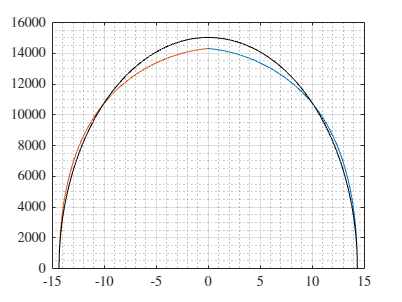

grid on
grid minor


hold off


MACcord = span_disc(MACpos)

MACcord = 6.4400

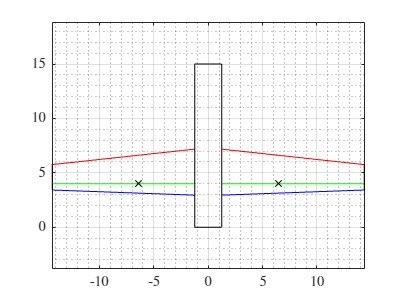

longitudinalMACac =  4;
fuselagedatum = 0;
feselageend = 15;


% plot(span_disc,c_y,'.')
% x_engine = quarterchord(ceil(length(c_y)*0.37))
% height_engine0.37*max(span_disc)*tand(5)-0.175*c_y(ceil(length(c_y)*0.37))-0.9
LEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) - 0.25 .* c_y;
TEsweep = (quarterchord-quarterchord(MACpos) + longitudinalMACac) + 0.75 .* c_y;
quarterchordplot = (quarterchord-quarterchord(MACpos) + longitudinalMACac);
%origin at quarterchord point of root chord
plot (span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
hold on
plot (span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
plot (span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot (-span_disc(fuselage_rad*100:end),TEsweep(fuselage_rad*100:end),'r')
hold on
plot (-span_disc(fuselage_rad*100:end),LEsweep(fuselage_rad*100:end),'b')
plot (-span_disc(fuselage_rad*100:end),quarterchordplot(fuselage_rad*100:end),'g')
plot (-span_disc(MACpos),quarterchordplot(MACpos),'xk')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([span_disc(end),span_disc(end)], [LEsweep(end),TEsweep(end)],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)], [LEsweep(fuselage_rad*100),TEsweep(fuselage_rad*100)],'k')
plot ([-span_disc(end),-span_disc(end)], [LEsweep(end),TEsweep(end)],'k')

plot ([span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),-span_disc(fuselage_rad*100)],[fuselagedatum,feselageend],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[fuselagedatum,fuselagedatum],'k')
plot ([-span_disc(fuselage_rad*100),span_disc(fuselage_rad*100)],[feselageend,feselageend],'k')

ylim([-7.5 7.5])
axis equal
hold off
grid on
grid minor

chordpos = 0;

Cl_alpha = 6.68

Cl_alpha = 6.6800

Mach = 0.45

Mach = 0.4500

S_rat = (Sref-2*fuselage_rad*c_y(fuselage_rad*100))/Sref

S_rat = 0.8907

FLF = 1.07*(1+(2*fuselage_rad/(semispan*2)))^2

FLF = 1.2645

yetaest = 0;
CL_alpha_curve = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)

CL_alpha_curve = 5.8735


V_stall = sqrt(WS*2/(rho*2.7))

V_stall = 67.0534

function [Sref, c_y,span_disc,quarterchord,MACpos] = planformcalc(AR, Sweep, Taper, c_bar)
s_1 = 0.25 * AR * (1+Taper); %_1 using 1 as reference root chord length
Sref_1 = (1 + Taper) * s_1;
span_disc_1 = [0:0.01:s_1];
c_y_1 = 1 - ((1-Taper)/s_1) * span_disc_1;
c_bar_1 = 2*trapz(span_disc_1,(c_y_1).^2)/Sref_1;
ratio = c_bar/c_bar_1; % dimensionalize using c_bar, can be changed later to root or tip chord length
s = ratio*s_1;
Sref = ratio * (1 + Taper) * s;
span_disc = [0:0.01:s];
c_y =  (1 - ((1-Taper)/s) * span_disc)*ratio;
temp1 = (c_y - c_bar).^2;
MACpos = find(temp1 == min(temp1));
quarterchord =  span_disc .* tand(Sweep);
end
function [CL_alpha_curve] = easyCLcurve(Cl_alpha, Mach, Sweep, AR, S_rat, FLF,yetaest)
beta = (1-Mach^2)^0.5;
if yetaest == 0
    yeta = Cl_alpha/(2*pi/beta);
else
    yeta = yetaest;
end
CL_alpha_curve = 2*pi*AR/(2+(4+((AR^2*beta^2)/(yeta^2))*(1+(tand(Sweep))^2/(beta^2)))^0.5) * S_rat * FLF;
end